Gp = tf(0.08,[10 1 0.1])


Gp =
 
        0.08
  ----------------
  10 s^2 + s + 0.1
 
Continuous-time transfer function.
Model Properties


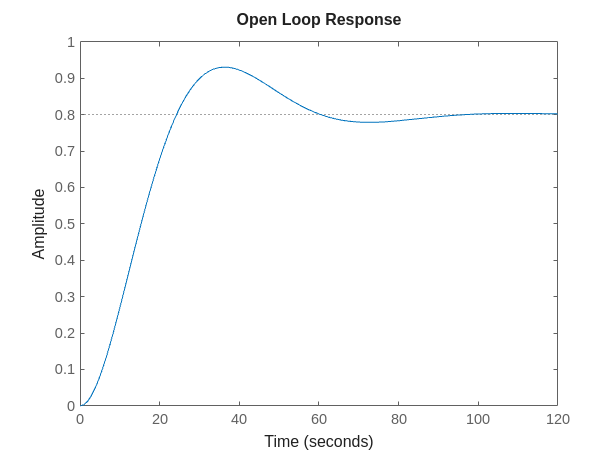

figure
step(Gp)
title('Open Loop Response')

- **Start with Kp**: Begin by increasing Kp until the system responds quickly, but without excessive oscillations.	

- **Introduce Kd:** Once oscillations appear, increase Kd to reduce them and improve damping.	

- **Add Ki:**	After achieving a reasonably damped response, introduce Ki to eliminate any steady-state error.  Be careful with integral gain, making this too high can lead to instability.	

- **Fine-tuning**: After setting all three gains, fine-tune each parameter to balance response speed, stability, and accuracy.

Initial Feedback

Kp = 1;
Kd = 0;
Ki = 0;
% Derivative feedback
Gd = feedback(Gp, tf(Kd*[1 0],1) )


Gd =
 
        0.08
  ----------------
  10 s^2 + s + 0.1
 
Continuous-time transfer function.
Model Properties


% Outer loop
Gcl = feedback((Kp+tf(Ki,[1 0])) * Gd , 1)


Gcl =
 
        0.08
  -----------------
  10 s^2 + s + 0.18
 
Continuous-time transfer function.
Model Properties


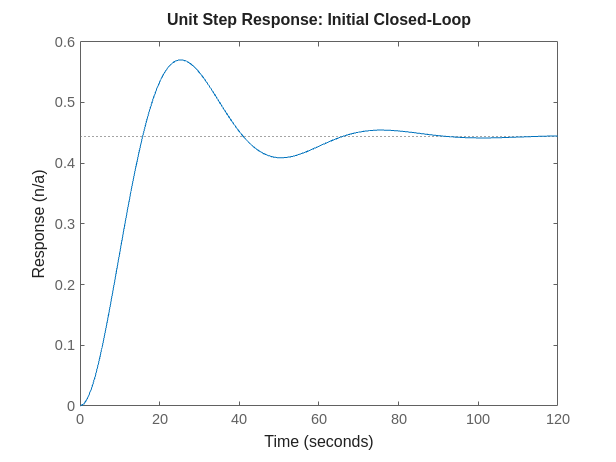


step(Gcl)
title('Unit Step Response: Initial Closed-Loop')
ylabel('Response (n/a)')

function gcl = closed_loop(Kp, Ki, Kd)
    Gp = tf(0.08,[10 1 0.1]);
    % Derivative feedback
    Gd = feedback(Gp, tf(Kd*[1 0],1) );
    % Outer loop
    gcl = feedback((Kp+tf(Ki,[1 0])) * Gd , 1);
end

- **Start with Kp**: Begin by increasing Kp until the system responds quickly, but without excessive oscillations.	

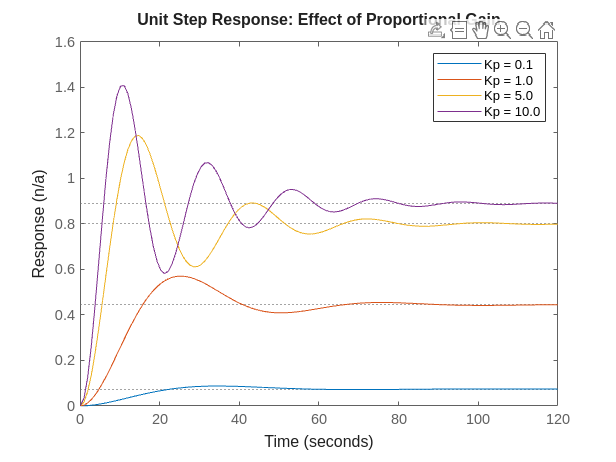

figure;
clf;
kkp = [0.1 1 5 10];

lstr = {};
for ii = 1:length(kkp)
    Kp = kkp(ii);
    step(closed_loop(Kp, 0, 0));
    hold on
    lstr{ii} = sprintf("Kp = %.1f", Kp);
end
legend(lstr)
title("Unit Step Response: Effect of Proportional Gain")
ylabel('Response (n/a)')

- **Introduce Kd:** Once oscillations appear, increase Kd to reduce them and improve damping.	

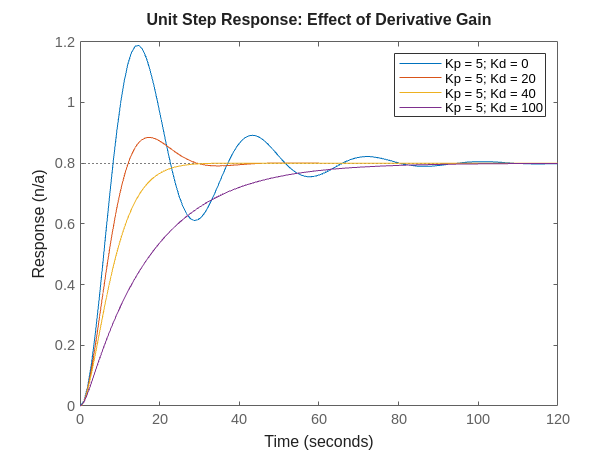

figure;
clf;
kkd = [0 20 40 100];
lstr = {};
Kp = 5;
for ii = 1:length(kkd)
    Kd = kkd(ii);
    step(closed_loop(Kp, 0, Kd));
    hold on

    lstr{ii} = sprintf("Kp = %.0f; Kd = %.0f", Kp, Kd);
end
legend(lstr)
title("Unit Step Response: Effect of Derivative Gain")
ylabel('Response (n/a)')


**Add Ki:**	After achieving a reasonably damped response, introduce Ki to eliminate any steady-state error.  Be careful with integral gain, making this too high can lead to instability.	

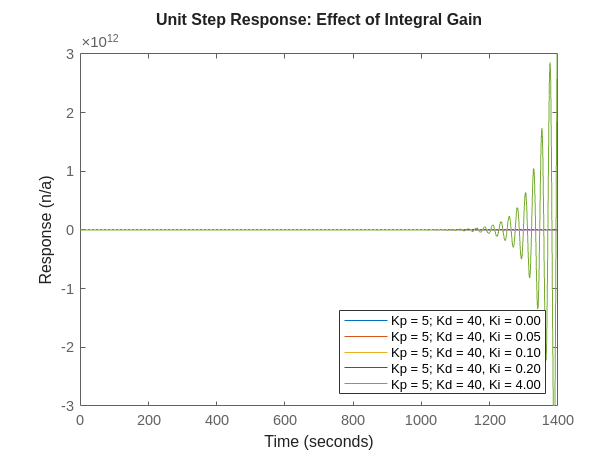

figure;
clf;
kki = [0 0.05 0.1 0.2 4];
lstr = {};
Kp = 5;
Kd = 40;
for ii = 1:length(kki)
    Ki = kki(ii);
    step(closed_loop(Kp, Ki, Kd));
    hold on
    lstr{ii} = sprintf("Kp = %.0f; Kd = %.0f, Ki = %.2f", Kp, Kd, Ki);
end
legend(lstr,'location', 'southeast')
title("Unit Step Response: Effect of Integral Gain")

ylabel('Response (n/a)')
